# **Assignment:  Sequence Statistics and Gene Finding**

**Bianca Caissotti di Chiusano **

**i6245461**

Like humans, Neanderthals had not only nuclear DNA, but also mitochondrial DNA in all their cells.  Like humans, the mitochondria of neanderthals contained 13 coding genes and 24 non-coding genes. The neanderthal mitochondrial genome has accession number 'NC_011137'.

- How does the number of genes stated above compare with the number of ORFs you find – explain your result. 

- Using what you have learnt above explore the neanderthal mitochondrial genome and find at least one *interesting* feature**.** Explain what you have found and what makes it interesting.

Make a new livescript with your working and explanations for this part and submit this file to the assignment on canvas.

Make sure to explain what you want to do, then put the code that does it, then finalise each section with an explanation of what you see in the results (for instance how do you interpret the plot, or the numbers you obtained).  Repeat this pattern for each major step/result in your report.  

First, use the command **getgenbank** to load the required data from GenBank, which is an open access sequence database. To retrieve sequence information of the neanderthal mitochondrial genome, use as input the accession number 'NC_011137'. 

By setting "**SequenceOnly**" to true, our variable called "data" will be a character array, representing only the sequence.

data = getgenbank('NC_011137', "SequenceOnly",true)

data = 'GATCACAGGTCTATCACCCTATTAACCACTCACGGGAGCTCTCCATGCATTTGGTATTTTCGTCTGGGGGGTGTGCACGCGATAGCATTGCGAGACGCTGGAGCCGGAGCACCCTATGTCGCAGTATCTGTCTTTGATTCCTGCCCCATTCCATTATTTATCGCACCTACGTTCAATATTACAGGCGAGCATACTTACTGAAGTGTGTTAATTAATTAATGCTTGTAGGACATAATAATAACGACTAAATGTCTGCACAGCTGCTTTCCACACAGACATCATAACAAAAAATTTCCACCAAACCCCCCCTCCCCCGCTTCTGGCCACAGCACTTAAACACATCTCTGCCAAACCCCAAAAACAAAGAACCCTAACACCAGCCTAACCAGATTTCAAATTTTATCTTTTGGCGGTATACACTTTTAACAGTCACCCCCTAACTAACACATTATTTTCCCCTCCCACTCCCATACTACTAATCTCATCAATACAACCCCCGCCCATCCTACCCAGCACACACCGCTGCTAACCCCATACCCCGAGCCAACCAAACCCCAAAGACACCCCCCACAGTTTATGTAGCTTACCTCCTCAAAGCAATACACTGAAAATGTTTAGACGGGCTCACATCACCCCATAAACAAATAGGTTTGGTCCTAGCCTTTCTATTAGCTCTTAGTAAGATTACACATGCAAGCATCCCCATTCCAGTGAGTTCACCCTCTAAATCACCACGATCAAAAGGGACAAGCATCAAGCACGCAACAATGCAGCTCAAAACGCTTAGCCTAGCCACACCCCCACGGGAAACAGCAGTGATAAGCCTTTAGCAATAAACGAAAGTTTAACTAAGCTATACTAACCCCAGGGTTGGTCAATTTCGTGCCAGCCACCGCGGTCACACGATTAACCCAAGTCAATAGAAGCCGGCGTAAAGAGTGTTTTAGATCACCCCCTCCCCAATAAAGCTAAAACTCACCTGAGTTGTAAAA

## **Question 1: How does the number of genes stated above compare with the number of ORFs you find – explain your result **

The Gene Finding Problem reads "Given a genomic sequence, how can we find the genes?". The first step to find the genes, is to find what we know as the "Candidate Genes". These are all opening reading frames within a sequence. 

Thus, with the **seqshoworfs** command we extract all of the ORFs within our sequence "data".

orfs = seqshoworfs(data)

orfs = 1×3 struct array with fields:
    Start
    Stop


From the output we can observe that there are 26 candidate genes in Frame 1, 23 in Frame 2 and 29 in Frame 3.

We call them candidate genes, because some of them may just have been generated by chance, stretches that are not genes just containing start and stop codons in the right order. 

Hence, we use Hypothesis Testing to decide how "unlikely" an ORF has to be in order to be accepted as a valid gene. Thus, to refrase, we need to identify the candidate genes that are longer than it would be expected by chance.

Lets first look at the number of codons and their likeliness within this sequence, by using the command **codoncount**

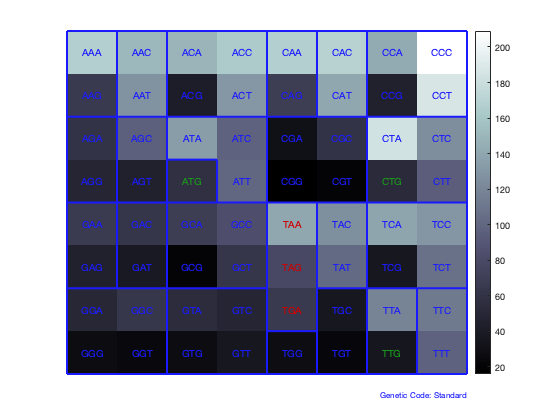

codon_count = struct with fields:
    AAA: 168
    AAC: 151
    AAG: 66
    AAT: 128
    ACA: 149
    ACC: 164
    ACG: 42
    ACT: 131
    AGA: 61
    AGC: 96
    AGG: 49
    AGT: 45
    ATA: 135
    ATC: 98
    ATG: 58
    ATT: 100
    CAA: 168
    CAC: 170
    CAG: 69
    CAT: 141
    CCA: 142
    CCC: 209
    CCG: 45
    CCT: 187
    CGA: 31
    CGC: 61
    CGG: 16
    CGT: 20
    CTA: 184
    CTC: 125
    CTG: 53
    CTT: 95
    GAA: 67
    GAC: 63
    GAG: 45
    GAT: 38
    GCA: 69
    GCC: 84
    GCG: 20
    GCT: 63
    GGA: 50
    GGC: 64
    GGG: 27
    GGT: 25
    GTA: 55
    GTC: 49
    GTG: 27
    GTT: 37
    TAA: 141
    TAC: 126
    TAG: 79
    TAT: 102
    TCA: 139
    TCC: 130
    TCG: 37
    TCT: 107
    TGA: 66
    TGC: 37
    TGG: 28
    TGT: 23
    TTA: 119
    TTC: 113
    TTG: 36
    TTT: 98


codonArray = codonArray(:,:,1) =

   168   149    61   135
   168   142    31   184
    67    69    50    55
   141   139    66   119


codonArray(:,:,2) =

   151   164    96    98
   170   209    61   125
    63    84    64    49
   126   130    37   113


codonArray(:,:,3) =

    66    42    49    58
    69    45    16    53
    45    20    27    27
    79    37    28    36


codonArray(:,:,4) =

   128   131    45   100
   141   187    20    95
    38    63    25    37
   102   107    23    98


[codon_count, codonArray] = codoncount(data, 'Figure', true)

From the Figure above we can observe that codon CCC is the most likely codon too occur, while GGG is the least likely. This makes sense, because as we will see below (During Question 2), base C occurs with a frequency of 0.3123, while G with 0.1316.

total_codons = 0;
for t = 1 : 4
    for i=1 : 4
        for j = 1 : 4
            total_codons = total_codons + codonArray(i, j, t);
        end
    end
end 
total_codons

total_codons = 5521

As there are 4 possible bases in a gene, but only a max of 3 bases per codon, there are in total 64 different possible codons (which is why we have a 4 by 4 by 4 array)

This sequence has a total of 5521 codons (counting the repetitions). This is important to note, because the example of Hypothesis testing seen in class was done assuming that all codons were equally likely. But as seen, above for example, codon CCC is more likely to occur than GGG.

The question is: given a start codon, what is the probability of a run of k non-stop codons (before encountering a stop codon)?

There are three possible stop-codons: TAA, TAG and TGA. Thus to calculate the number of non-stop codons we do: total_codons - (sum of stop codons in the sequence), which is equal to 5235 codons

% total number of non-stop codons = total codons minus the sum of all stop
% codons in the sequence
difference = total_codons - (codon_count.TAA + codon_count.TAG + codon_count.TGA)

difference = 5235

Thus the probability of P(run of k non stop codons) is: 0.9482

%The probability that any non-stop codon occurs 
p_k_nonstop = difference ./ total_codons

p_k_nonstop = 0.9482

If we want 95% chance that an ORF length is longer than would be expected by chance: P(run of k non-stop codons) < 0.05

0.05 is our alpha value, as we are looking at 95% chance, meaning that 5% of the time the data will appear to be significant.

This equates to (0.9482)^k < 0.05. We use log properties to calculate the k.

k = log(0.05)/log(p_k_nonstop)

k = 56.3191

We round k to 56. Hence, we can say that we will discard all ORFs of length k <= 58 (56 plus one start codon and one stop codon), thus removing 95% of previously calculated ORFs

Calculate the new valid ORFs by using the comman **seqshoworfs** and setting the **Minimum Length** to be 59

valid_orfs = seqshoworfs(data, "MinimumLength", 59)

valid_orfs = 1×3 struct array with fields:
    Start
    Stop


frame_number = 3;
count = 0;
% count the number of ORFs from the newly generated table
for i = 1: frame_number    
   count = count + length(valid_orfs(i).Start);
end
count

count = 14

The newly calculated significant ORFs are in total 14. This makes much more sense, as the mitochondria of neanderthals contain 13 coding genes. 

It is also important to note that all of the other shorter ORFs in the sequence, and the rest of the DNA, are valid and crucial structural elements, also referred to as junk. This is in fact, usually found in regions of Eukaryotic genomes, as they contain lots of repetitions.

The number of significant ORFs depends on the chance that we are testing for. For example is we want a:

97% probability that an ORF length is longer than would be expected by chance - 10 valid ORFs

96% probability that an ORF length is longer than would be expected by chance - 12 valid ORFs

k_1 = log(0.04)/log(p_k_nonstop)

k_1 = 60.5141

valid_orfs_1 = seqshoworfs(data, "MinimumLength", 62)

valid_orfs_1 = 1×3 struct array with fields:
    Start
    Stop


frame_number = 3;
count = 0;
% count the number of ORFs from the newly generated table
for i = 1: frame_number    
   count = count + length(valid_orfs_1(i).Start);
end
count

count = 12

## Question 2: Using what you have learnt above explore the neanderthal mitochondrial genome and find **at least one *****interesting***** feature.** Explain what you have found and what makes it interesting.

To further explore the neanderthal mitochondrial genome, first check how many times all possible bases are occurring.

all_bases = basecount(data, 'Ambiguous', 'individual')

all_bases = struct with fields:
    A: 5107
    C: 5174
    G: 2180
    T: 4104
    R: 0
    Y: 0
    K: 0
    M: 0
    S: 0
    W: 0
    B: 0
    D: 0
    H: 0
    V: 0
    N: 0


One interesting observation is that there are no ambigious symbols within the sequence.

We can then, further check and plot the frequencies of the bases occurrence.

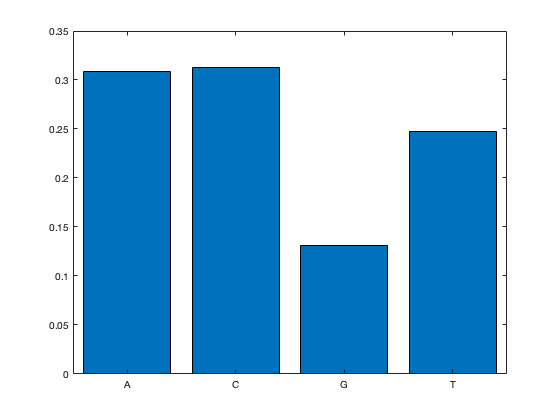

% calculate frequency 
freq_A = all_bases.A ./ length(data);
freq_C = all_bases.C ./ length(data);
freq_G = all_bases.G ./ length(data);
freq_T = all_bases.T ./ length(data);
x = categorical({'A', 'C', 'G', 'T'});
y = [freq_A, freq_C, freq_G, freq_T];
bar(x,y)

% Table
bases = ["A"; "C"; "G"; "T"];
count = [all_bases.A; all_bases.C; all_bases.G; all_bases.T];
frequency = [freq_A; freq_C; freq_G; freq_T];
frequency_table = table(bases,count,frequency)

frequency_table = 4×3 table
    bases    count    frequency
    _____    _____    _________

     "A"     5107       0.3083 
     "C"     5174      0.31235 
     "G"     2180       0.1316 
     "T"     4104      0.24775 


From the above frequency table and bar graph, some interesting observations are that C is the most frequent nucleotide, and G is the least frequent. 

This is interesting, because we learned that there are 3 reading frames, as we start reading in the following way:

Frame 1: ATG

Frame 2: A

Frame 3: AT

Considering that the start codon in an ORF is ATG, thus contains G (which is the least likely nucleotide in our sequence), and in the first frame we start from ATG, we can even see from the solutions of Question 1, that when calling **seqshoworfs, **Frame 1 always contains the least numbers of start codons.

And the reason for that could be because G is much less common.

Even, continuing exploring the sequence, we can see that when calling command **dimercount, **every dimer containing G is the least likely to occur. While the dimers CC and AA, thus also CA or AC are the most common as C and A are much more frequent. 

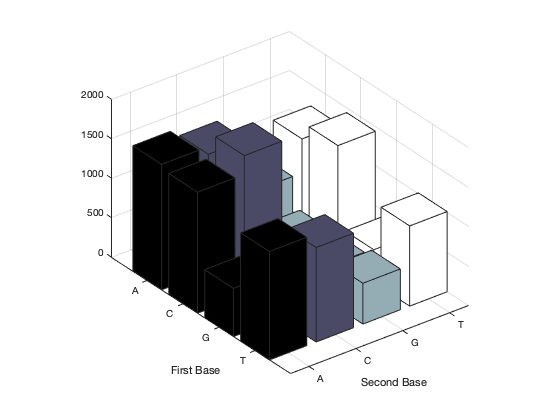

ans = struct with fields:
    AA: 1589
    AC: 1490
    AG: 799
    AT: 1229
    CA: 1533
    CC: 1769
    CG: 431
    CT: 1441
    GA: 611
    GC: 718
    GG: 432
    GT: 418
    TA: 1374
    TC: 1197
    TG: 517
    TT: 1016


dimercount(data, 'chart', 'bar')

Lastly, we can show nucleotide density through sliding window plots. These show that frequencies of nuclotides throughout the sequence.

On Matlab, by default, the command ntdensity will divide the length of the provided sequence by 20. And measure the frequency. Again, we can observe that C followed by A and T are more frequent than G. 

Moreover, we can observe that A is much more frequent at the beggining of the sequence, while C is less frequent at the beggining of the sequence.

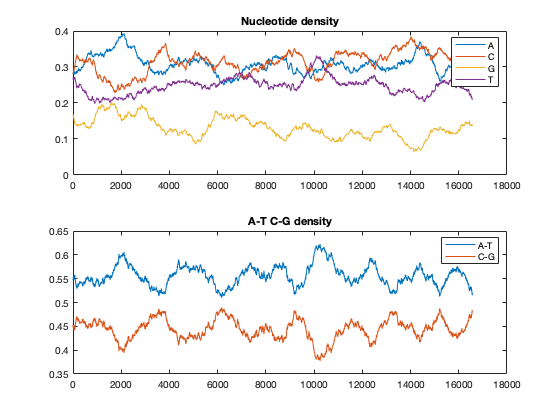

density = struct with fields:
    A: [1×16565 double]
    C: [1×16565 double]
    G: [1×16565 double]
    T: [1×16565 double]


% Default is length(SeqNT)/20. (From Documentation)
density = ntdensity(data)

We can slide the window size. The smaller the window size, the higher the variance in base composition. 

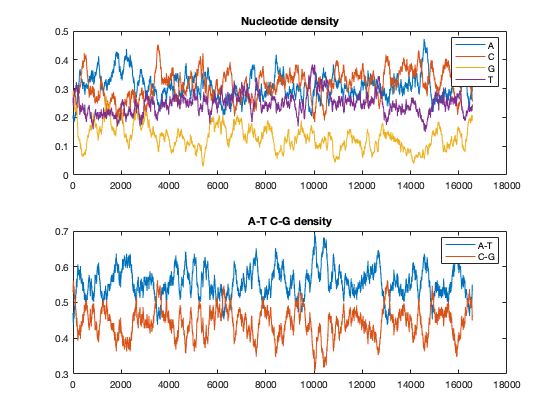

density_1 = struct with fields:
    A: [1×16565 double]
    C: [1×16565 double]
    G: [1×16565 double]
    T: [1×16565 double]


figure;
density_1 = ntdensity(data, 'Window', 200)

However, while bigger window sizes may not take into account the fluctuations of base compositions in smaller regions, also the use of small window sizes may lead to results such as the following plots, which might be difficult to interpret. Thus choosing the correct window size needs to be done carefully.

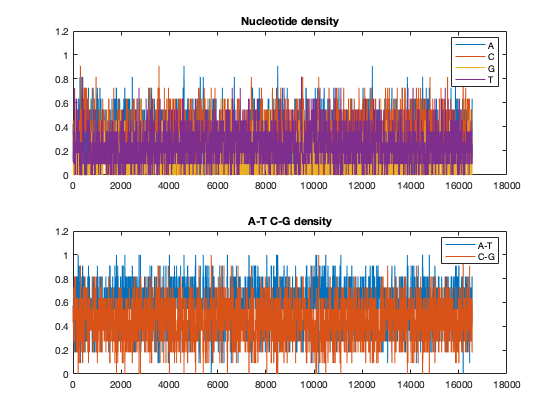

density_2 = struct with fields:
    A: [1×16565 double]
    C: [1×16565 double]
    G: [1×16565 double]
    T: [1×16565 double]


figure;
density_2 = ntdensity(data, 'Window', 10)